clc; clear all; close all;

LOADING OF DATA

filename = "alldata_1_for_kaggle.csv";
data = readtable(filename,'TextType','string');
head(data)

    Var1          Var2                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                

data(1, :) = []; %Removing the first row
data(:, 1) = []; %Removing the first indexing column
head(data)

          Var2                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                         

%Loking at the unique class in the data
uniqueElements = unique(data.Var2);
disp(uniqueElements);

    "Colon_Cancer"
    "Lung_Cancer"
    "Thyroid_Cancer"



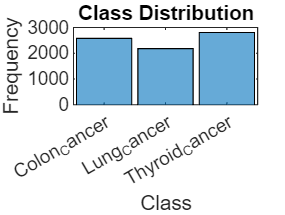

          Var2                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                         

data.class = categorical(data.Var2, 'Ordinal', true);
figure
histogram(data.class);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

DATA SPLITTING


numObservations = height(data);

% split ratios
trainRatio = 0.6;% the size is not enough so we use more for training
valRatio = 0.2;
testRatio = 0.2;

%number of observations for each set
numTrain = round(trainRatio * numObservations);
numVal = round(valRatio * numObservations);
numTest = numObservations - numTrain - numVal;  % To ensure full use of data

% Randomly shuffle the data
shuffledData = data(randperm(numObservations), :);

% Split the data
trainData = shuffledData(1:numTrain, :);
valData = shuffledData(numTrain+1:numTrain+numVal, :);
testData = shuffledData(numTrain+numVal+1:end, :);

% Display the sizes of each set
disp('Training Data:');

Training Data:


disp(size(trainData));

        4542           3




disp('Validation Data:');

Validation Data:


disp(size(valData));

        1514           3




disp('Testing Data:');

Testing Data:


disp(size(testData));

        1514           3



textDataTrain = trainData.Var3;
textDataValidation = valData.Var3;
textDataTest = testData.Var3

textDataTest = 1514×1 string array
    ""The second patient with EGFR mutation achieved the longest PFS and OS (727 and 1249 days respectively). .0087629.g007  Kaplan-Meier estimates of PFS and OS. No statistically significant difference (P?=?0.007) in PFS was observed between metabolic non-progressive (mNP) patients (median PFS 292 days ; range 190“727) and metabolic (mP) progressive patients (median PFS 64 days ; range: 37“216). Improved PFS in non-progressive patients was associated with prolonged OS (mNP; n?=?4; median OS: 1031 days ; 296 to 1249 days versus mP; n?=?8 ; 337 5 days ; 71 to 734 days) (HR 0.34; 95% CI 0.06 to 0.84; P?=?0.03). Discussion Despite the widespread use of [18F]FDG-PET/CT in NSCLC staging a large-scale study recently failed to confirm an overall survival gain in NSCLC patients.[17] This result highlights the value of [18F]FDG-PET/CT in unmet clinical needs such as prediction of residual NSCLC after surgery[18] neoadjuvant therapy[19] or antineoplastic therap

YTrain      = trainData.class;
YValidation = valData.class;
YTest = testData.class;

WorldCloud Videw Of Train Data 

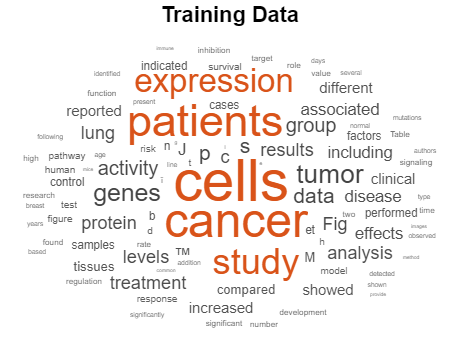

%Caution this take very long time becuase of the data size
figure
wordcloud(textDataTrain);
title("Training Data")

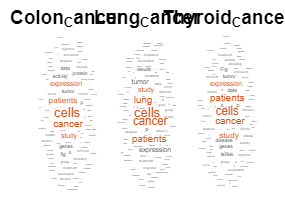


% Data Exploration for sample of Train
% Write code here
idxCO = cellfun(@(x) ismember("Colon_Cancer", x), trainData.Var2);
idxST = cellfun(@(x) ismember("Lung_Cancer", x), trainData.Var2);
idxCOST = cellfun(@(x) ismember("Thyroid_Cancer", x), trainData.Var2);

figure
subplot(1,3,1)
wordcloud(textDataTrain(idxCO));
title("Colon_Cancer")

subplot(1,3,2)
wordcloud(textDataTrain(idxST));
title("Lung_Cancer")

subplot(1,3,3)
wordcloud(textDataTrain(idxCOST));
title("Thyroid_Cancer")

%Preprocessing Data 
documentsTrain      = preprocessText(textDataTrain);
documentsValidation = preprocessText(textDataValidation);
documentsTest       = preprocessText(textDataTest);

## Encoding

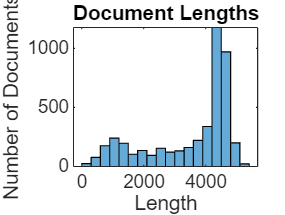

enc = wordEncoding(documentsTrain);

documentLengths = doclength(documentsTrain);
figure
histogram(documentLengths)
title("Document Lengths")
xlabel("Length")
ylabel("Number of Documents")

sequenceLength  = 10; %Did not use the ideal sequence length, however 10 works fine with LSTM prediction
XTrain          = doc2sequence(enc,documentsTrain,'Length',sequenceLength);
XValidation     = doc2sequence(enc,documentsValidation,'Length',sequenceLength);
XTest           = doc2sequence(enc,documentsTest,'Length',sequenceLength);

inputSize           = 1;
embeddingDimension  = 50;
numHiddenUnits      = 100;

numWords    = enc.NumWords;
numClasses  = numel(categories(YTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords) % Works better with it
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   6×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 201245 unique words
     3   ''   LSTM                    LSTM with 100 hidden units
     4   ''   Fully Connected         3 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex

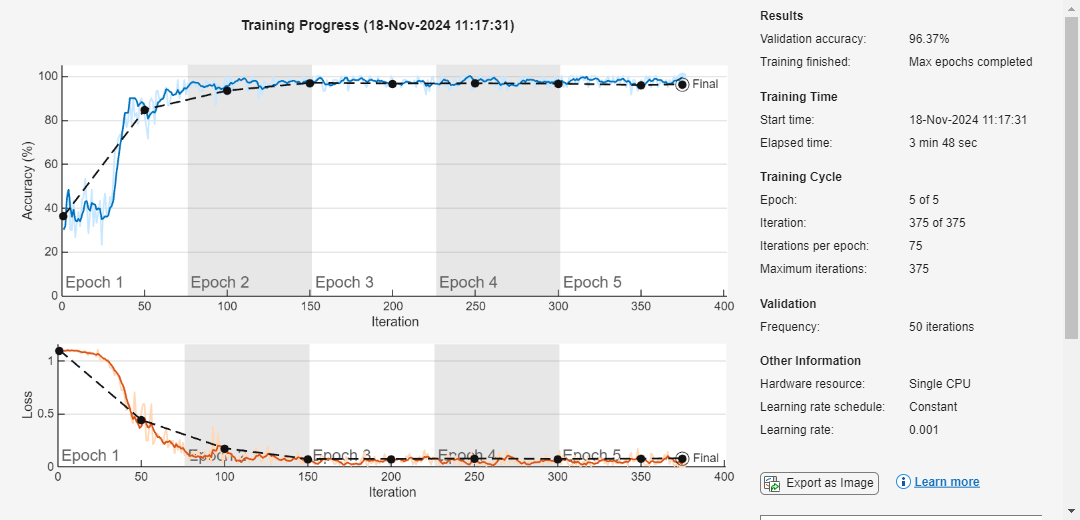


options = trainingOptions('adam', ...
    'MiniBatchSize', 60, ...
    'GradientThreshold',5, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'Plots','training-progress', ...
    'Verbose',false,...
    'MaxEpochs', 5);

net = trainNetwork(XTrain,YTrain,layers,options);

labelsNew = classify(net,XTest)

labelsNew = 1514×1 categorical array
     Thyroid_Cancer 
     Colon_Cancer 
     Lung_Cancer 
     Lung_Cancer 
     Colon_Cancer 
     Thyroid_Cancer 
     Colon_Cancer 
     Thyroid_Cancer 
     Thyroid_Cancer 
     Thyroid_Cancer 
     Lung_Cancer 
     Thyroid_Cancer 
     Lung_Cancer 
     Colon_Cancer 
     Thyroid_Cancer 
     Colon_Cancer 
     Colon_Cancer 
     Thyroid_Cancer 
     Colon_Cancer 
     Thyroid_Cancer 
     Colon_Cancer 
     Lung_Cancer 
     Colon_Cancer 
     Thyroid_Cancer 
     Lung_Cancer 
     Lung_Cancer 
     Colon_Cancer 
     Colon_Cancer 
     Thyroid_Cancer 
     Thyroid_Cancer 


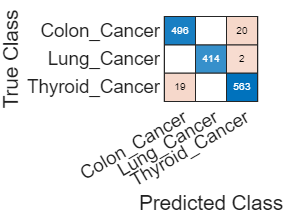

figure
confusionchart(YTest,labelsNew)

## **Preprocessing Data For RNN**

YTrainOneHot = onehotencode(YTrain, 2, 'ClassNames', categories(YTrain));
YValidationOneHot = onehotencode(YValidation, 2, 'ClassNames', categories(YValidation));
YTestOneHot = onehotencode(YTest, 2, 'ClassNames', categories(YTest));

rdata = rnnpt(textDataTrain)

rdata =   4542×1 tokenizedDocument:

    1129 tokens: covid19 brain injury medical imaging review biology 0cthis cover version version undergo review final version early please process errors affect content apply journal pertain brain heart injury medical imaging covid review jasjit faimbe faium fapvs1 anudeep puvvula fcd12 mainak biswas misha gavino inder singh ronald chadha johri fase10 miguel sanches phd11 khanna facc12 phd13 sophie fesc14 laird facp15 pareek martin miner david sobel petros phd20 durga misra frcp21 vikas agarwal frcp21 kitas frcp22 puneet mch24 raghu kolluri jagjit mustafa almaini dhanjil fsvu29 meyypan frcr30 saxena andrew frcs31 aditya sharma vijay rathore janet mostafa fatemi faimbe fieee faium35 alizad faimbe faium36 vijay phd37 naidu fieee39 1stroke 2annu nellore india kolkata bengal india school azienda italy italy 7stroke imaging study germany ontario canada systems tecnico lisboa ap

renc = wordEncoding(rdata);
% Find unique words
uniqueWords = renc.Vocabulary;
numUniqueWords = renc.NumWords;         % Total number of unique words
numDocuments = numel(renc)

numDocuments = 1

RNN_XTrain = cell(1, numDocuments);

% One-hot encoding for each document
for i = 1:numDocuments
    words = string(rdata(i).Vocabulary);  % Extract tokens as strings
    
    % Target sequence length
    sequenceLength = 156;                 % Number of words in the document
    
    % Get indices of words in the vocabulary
    [~, idx] = ismember(words, uniqueWords);
    
    % Initialize one-hot encoded matrix
    X = zeros(numUniqueWords, sequenceLength);
    
    % One-hot encode each word in the document
    for j = 1:min(sequenceLength, numel(words))
        X(idx(j), j) = 1;
    end
    
    RNN_XTrain{i} = X;  % Store the one-hot encoded matrix for the document
end

%This part of the code is to find the maximum length of sequences in Train
maxState = 1;
for i = 1:numel(RNN_XTrain)
    [row, col] = size(RNN_XTrain{1,i});
    maxState = max(col, maxState);
end

%Applying Paddings to sequence 

for i = 1:numel(RNN_XTrain)
    X = [];
    X = XTrain{1,i};
    X(:, end:maxState) = 0;
    RNN_XTrain{1,i} = X;

end



RNN

feedbackDelays = 1:5;
% Define network layers using RNN
net = layrecnet(feedbackDelays, numHiddenUnits);

% Define training options
options = trainingOptions('adam', ...
    'MiniBatchSize', 200, ...
    'GradientThreshold', 2, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XValidation, YValidationOneHot}, ...
    'Plots', 'training-progress', ...
    'Verbose', false, ...
    'MaxEpochs', 3);

% Train the network
Rnet = train(net, XTrain, YTrainOneHot,[], [], options);

Dot indexing is not supported for variables of this type.

labelsNew = classify(net,XTest)
figure
confusionchart(XTest,labelsNew)

**FUNCTIONS FOR DATA PREPROCESSING**

function rnndoc = rnnpt(data)

rnndoc = tokenizedDocument(data);
rnndoc = removeStopWords(rnndoc);
rnndoc = removeShortWords(rnndoc,4); % Remove words that are shorter than 2
rnndoc = removeLongWords(rnndoc,8); % Remove words that are longer than 15
rnndoc = lower(rnndoc);
% Erase punctuation.
rnndoc = erasePunctuation(rnndoc);

end

function documents = preprocessText(textData)

% Tokenize the text.
documents = tokenizedDocument(textData);
% Convert to lowercase.
documents = lower(documents);
% Erase punctuation.
documents = erasePunctuation(documents);

end

